% Load the data from the file 'data6.mat'
load("data6.mat");

% The ECG sampling rate is 1000 Hz
FS = 1000;

% QRS detector operates on 200 Hz signals
FS_QRS = 200;

% The number of subjects
N = numel(data);

% Windowing length
window = 50;

% Number of overlapped samples 
nbroverlap = 45;

% Specify nfft parameter as empty. 
nfft = [];

% Minimum spectrogram threshold
th = -30; 

% Using the pre-extracted cardiac cycles (struct 'cycles'), compute the spectrogram for each subject
% Store the results in a similar 1xN struct array called 'SPCs' with the fields s, f, t, and p corresponding to the outputs of the function 'spectrogram'
% E.g. SPCs(3).p is the power spectral density spectrogram (a matrix) of the subject 3.
[s, f, t, p] = arrayfun(@(x) spectrogram(x.PCG, window, nbroverlap, nfft, FS, 'yaxis', MinThreshold=th),cycles,UniformOutput=false)

s = 1×5 cell array
    {129×351 double}    {129×491 double}    {129×261 double}    {129×171 double}    {129×281 double}


f = 1×5 cell array
    {129×1 double}    {129×1 double}    {129×1 double}    {129×1 double}    {129×1 double}


t = 1×5 cell array
    {[0.0250 0.0300 0.0350 0.0400 0.0450 0.0500 0.0550 0.0600 0.0650 0.0700 0.0750 0.0800 0.0850 0.0900 0.0950 0.1000 0.1050 0.1100 0.1150 0.1200 0.1250 0.1300 0.1350 0.1400 0.1450 0.1500 0.1550 0.1600 0.1650 0.1700 0.1750 0.1800 0.1850 0.1900 0.1950 0.2000 0.2050 0.2100 0.2150 0.2200 0.2250 0.2300 0.2350 0.2400 0.2450 0.2500 0.2550 0.2600 0.2650 0.2700 0.2750 0.2800 0.2850 0.2900 0.2950 0.3000 0.3050 0.3100 0.3150 0.3200 0.3250 0.3300 0.3350 0.3400 0.3450 0.3500 0.3550 0.3600 0.3650 0.3700 0.3750 0.3800 0.3850 0.3900 0.3950 0.4000 0.4050 0.4100 0.4150 0.4200 0.4250 0.4300 0.4350 0.4400 0.4450 0.4500 0.4550 0.4600 0.4650 0.4700 0.4750 0.4800 0.4850 0.4900 0.4950 0.5000 0.5050 0.5100 0.5150 0.5200 0.5250 0.5300 0.5350 0.5400 0.5450 0.5500 0.5550 0.5600 0.5650 0.5700 0.5750 0.5800 0.5850 0.5900 0.5950 0.6000 0.6050 0.6100 0.6150 0.6200 0.6250 0.6300 0.6350 0.6400 0.6450 0.6500 0.6550 0.6600 0.6650 0.6700 0.6750 0.6800 0.6850 0.6900 0.6950 0.7000 0.7050 0.7100 0.7150 0.

p = 1×5 cell array
    {129×351 double}    {129×491 double}    {129×261 double}    {129×171 double}    {129×281 double}


SPCs = struct('s', s, 'f', f, 't', t, 'p', p)

SPCs = 1×5 struct array with fields:
    s
    f
    t
    p



% Using the full data (struct 'data'), find the QRS complexes using the function 'QRSDetection'
% Store only the QRS onset indice vectors of each subject in the elements of the 1xN cell array 'onsets'
% Note: QRS detection works at a lower data rate of 200 Hz instead of 1000 Hz, so you must resample the data first
%       Also you must map the detected onsets back to the original sampling rate by multiplying with the correct factor
onsets = arrayfun(@(x) QRSDetection(resample(x.ECG, FS_QRS, FS)) * 5, data, 'UniformOutput',false)

onsets = 1×5 cell array
    {[150 1100 2055 3025 3985 4965 5920 6885 7845 8815 9765 10760 11770 12755 13720 14735 15735 16720 17720 18745 19765 20790]}    {[685 2060 3450 4845 6210 7335 8720 9995 11210 12610 13815 14940 16215 17460 18510 19645]}    {[65 675 1265 1825 2430 3050 3615 4205 4825 5410 5995 6635 7245 7825 8525 9370 9990 10635 11275 11840 12425 13030 13595 14145 14730 15325 15880]}    {[170 1055 1500 1940 2390 2835 3280 3725 4610 5045 5490 5920 6365 7235 7670 8105 8550 8985 9425 9860 10740 11185 11625 12075 12515 12965 13395 13840 14275 14725 15155 15600 16030 16475 16905 17350 17790 18675 19115]}    {[145 855 1540 2230 2965 3765 4575 5310 6030 6780 7565 8360 9085 9805 10560 11325 12050 12775 13515 14285 15000 15530 16415 17065 17750 18480 19165 19845 20550 21290]}



% The systolic part of the PCG signal is expected to span this many samples starting from the QRS onset in each beat
segment_length = 300;

% Using the previously computed onsets, for each subject 
% pick all their PCG segments corresponding to the systolic parts in a 1xN cell array 'systoles'
% So, each cell corresponds to a subject, and contains a m-by-segment_length sized matrix of their m PCG segments
idx = cell(1, N);
for i = 1:N
    for onset = onsets{i}
        idx{i} = [idx{i}, onset:onset+segment_length-1];
    end
end
systoles = arrayfun(@(x) reshape(data(x).PCG(idx{x}), segment_length, [])', 1:N, UniformOutput=false)

systoles = 1×5 cell array
    {22×300 double}    {16×300 double}    {27×300 double}    {39×300 double}    {30×300 double}


ans =     0.4295    0.4834    0.2797   -0.0493   -0.2196   -0.2760   -0.1897   -0.0151    0.1039    0.1424    0.0905    0.0359    0.0372    0.0258   -0.0410   -0.1508   -0.1720   -0.0734    0.0526    0.1338    0.1907    0.1799    0.0929   -0.0645   -0.1553   -0.1884   -0.1973   -0.2364   -0.1916   -0.0359    0.1140    0.1778    0.1524    0.0694    0.0230   -0.0504   -0.1903   -0.3595   -0.4269   -0.5489   -0.6230   -0.5153   -0.4198   -0.3233   -0.1465    0.1453    0.2908    0.2684    0.1620    0.0349


PSDs = struct([]);
for i = 1:N
    [pxx,f] = arrayfun(@(y) pwelch(systoles{i}(y,:),[],[],[],FS), 1:size(systoles{i}, 1), UniformOutput=false);
    PSDs(i).Pxx = cell2mat(pxx)';
    PSDs(i).F = f{1};
    PSDs(i).Pxx_mean = mean(PSDs(i).Pxx, 1);
end

% For each subject, compute the power spectral density (PSD) of all the PCG segments separately
% Use the 'pwelch' function with the default arguments but specifying the sampling rate
% Store the results in a 1xN struct array 'PSDs' with the fields Pxx and F corresponding to the outputs of the pwelch function
% In addition, add the field Pxx_mean which is the average of all the PSD of that subject averaged across the beats
% Thus, PSDs(i).Pxx is a mxk matrix, PSDs(i).F is a kx1 vector, and PSDs(i).Pxx_mean is a 1xk vector
PSDs = struct([]);
for i = 1:N
    [pxx,f] = arrayfun(@(y) pwelch(systoles{i}(y,:),[],[],[],FS), 1:size(systoles{i}, 1), UniformOutput=false);
    PSDs(i).Pxx = cell2mat(pxx)';
    PSDs(i).F = f{1};
    PSDs(i).Pxx_mean = mean(PSDs(i).Pxx, 1);
end

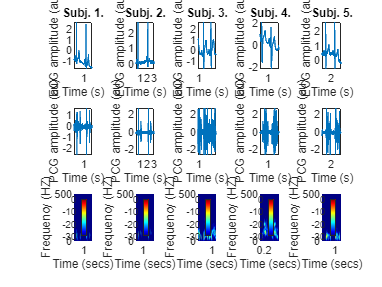

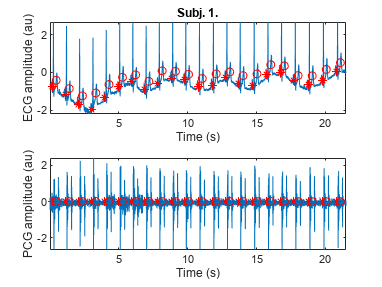

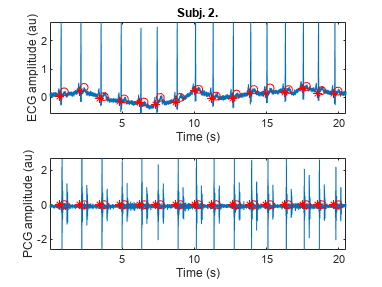

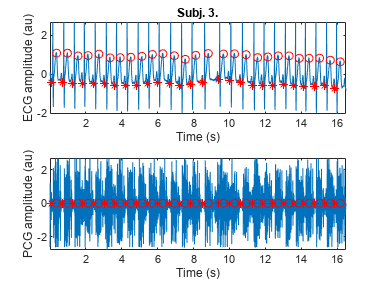

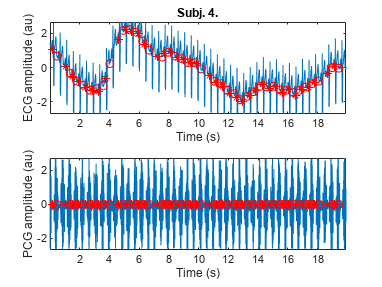

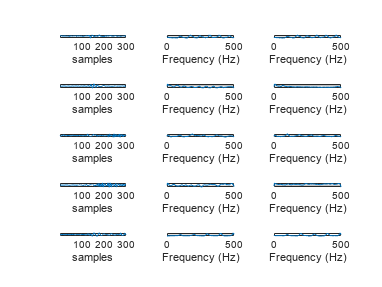

visualize_all(N, cycles, SPCs, th, data, onsets, segment_length, systoles, PSDs)